# A Guide to MATLAB

## Practice Set A: Algebra and Arithmetic

clear; 1111-345

ans = 766

format long
a = exp(14)

a =      1.202604284164777e+06


b = 382801*pi

b =      1.202604809386826e+06


a<b

ans = logical
   1


x = [2709/1024, 10583/4000, 2024/765]

x =    2.645507812500000   2.645750000000000   2.645751633986928


y = x - sqrt(7)

y = 	1.0e+-3 *

  -0.243498564590716  -0.001311064590670   0.000322922337315


[e,i] = min(abs(y))

e =      3.229223373146795e-07


i =      3


clear; cosh(0.1)

ans =    1.005004168055804


log(2)

ans =    0.693147180559945


atan(1/2)

ans =    0.463647609000806


clear; syms x y z;
eqns = [3*x+4*y+5*z==2, 2*x-3*y+7*z==-1, x-6*y+z==3];
[solx, soly, solz] = solve(eqns, [x y z])

$$solx = \frac{241}{92}$$

$$soly = -\frac{21}{92}$$

$$solz = -\frac{91}{92}$$

M = [3 4 5; 2 -3 7; 1 -6 1]

M =      3     4     5
     2    -3     7
     1    -6     1


b = M*[solx; soly; solz]

$$b = \left(\begin{array}{c} 2\\ -1\\ 3 \end{array}\right)$$

eqns = [3*x-9*y+8*z==2, 2*x-3*y+7*z==-1, x-6*y+z==3];
[solx, soly, solz] = solve(eqns, [x y z])

$$solx = -\frac{5}{3}$$

$$soly = -\frac{7}{9}$$

$$solz = 0$$

M = [3 -9 8; 2 -3 7; 1 -6 1]

M =      3    -9     8
     2    -3     7
     1    -6     1


b = M*[solx, soly, solz]'

$$b = \left(\begin{array}{c} 2\\ -1\\ 3 \end{array}\right)$$

clear; syms x y;
factor(x^4-y^4)

$$ans = \left(\begin{array}{ccc} x-y & x+y & x^{2}+y^{2} \end{array}\right)$$

clear; syms x;
simplify(1/(1+1/(1+1/x)))

$$ans = \frac{x+1}{2\,x+1}$$

simplify((cos(x))^2-(sin(x))^2)

$$ans = \cos\left(2\,x\right)$$

3^301

ans = 4.1067e+143

pretty(sym(3^301))

4106744371757651608203616941748438027875460921522632042760\
6142113768011500110994731738134859554642324317797033442127\
3291830236683739419899854848



clear; syms x p q
solve(67*x+32==0)

$$ans = -\frac{32}{67}$$

vpa(solve(67*x+32==0), 15)

$$ans = -0.477611940298507$$

solve(x^3+p*x+q, x)

$$ans = \left(\begin{array}{c} \mathrm{root}\left(z^{3}+p\,z+q,z,1\right)\\ \mathrm{root}\left(z^{3}+p\,z+q,z,2\right)\\ \mathrm{root}\left(z^{3}+p\,z+q,z,3\right) \end{array}\right)$$

solve(exp(x)==8*x-4, 'Real', true)

$$ans = \left(\begin{array}{c} \frac{1}{2}-W_{0}\left(-\frac{\sqrt{\mathrm{e}}}{8}\right)\\ \frac{1}{2}-W_{-1}\left(-\frac{\sqrt{\mathrm{e}}}{8}\right) \end{array}\right)$$

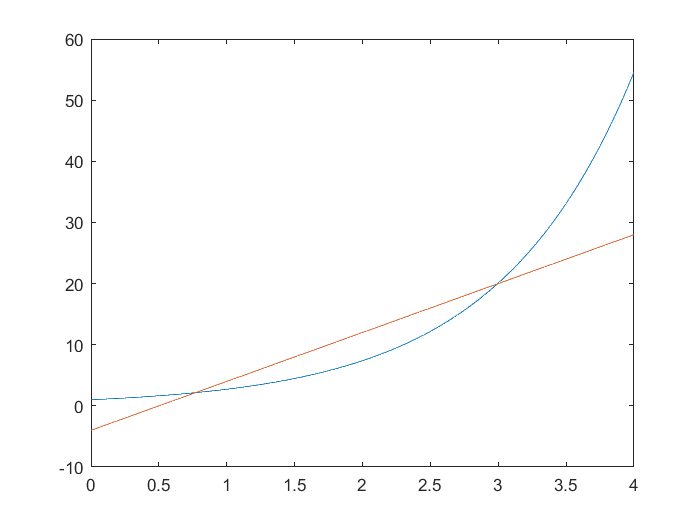

x = 0:0.01:4; plot(x, exp(x), x, 8*x-4)

fzero(@(x) exp(x)-8*x+4, 1)

ans = 0.7700

fzero(@(x) exp(x)-8*x+4, 3)

ans = 2.9929

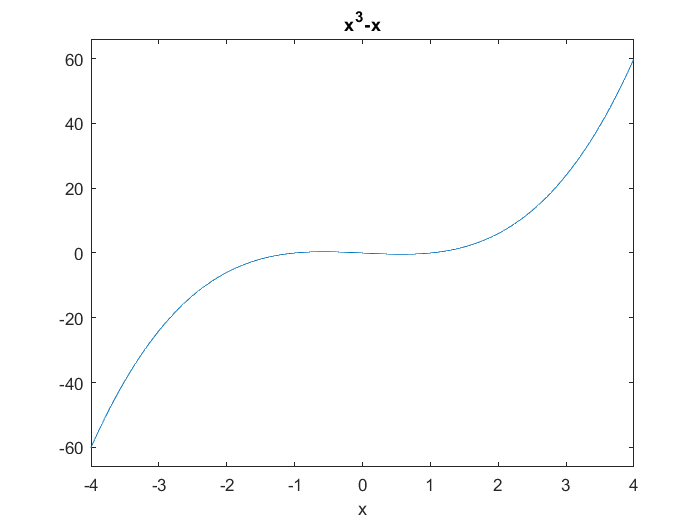

clear;
ezplot(@(x) x.^3-x, [-4,4])

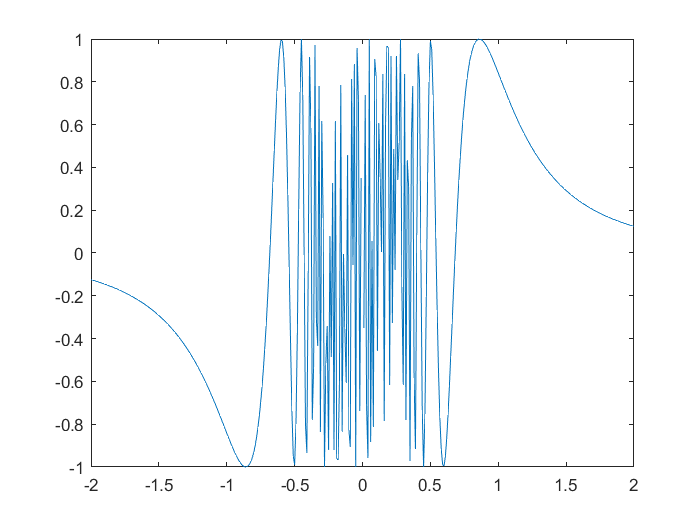

x = -2:0.01:2; plot(x, sin(1./x.^3))

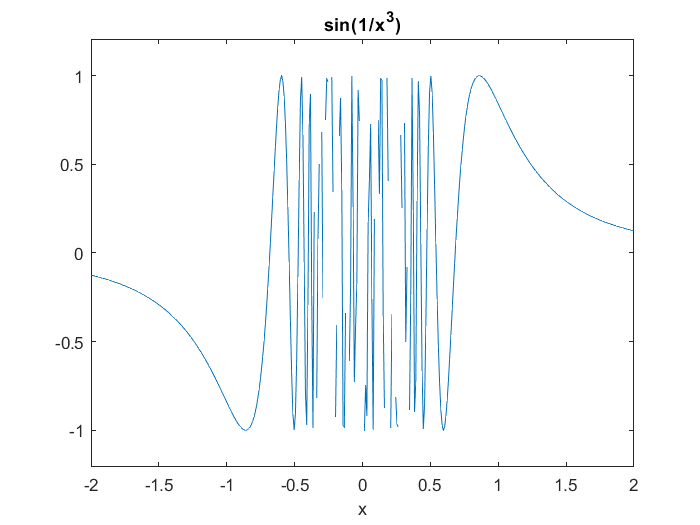

ezplot(@(x) sin(1./x.^3), [-2,2])

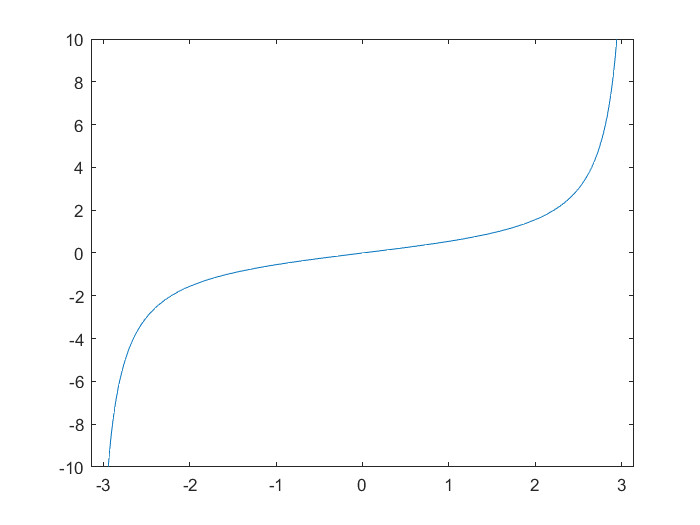

fplot(@(x) tan(x./2), [-pi, pi])
axis([-pi, pi, -10, 10])

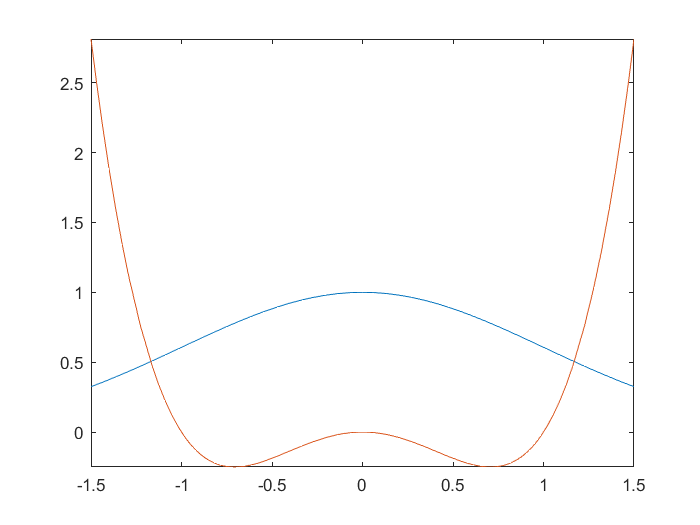

fplot(@(x) exp(-x.^2./2), [-1.5, 1.5])
hold on
fplot(@(x) x.^4-x.^2, [-1.5, 1.5])
hold off

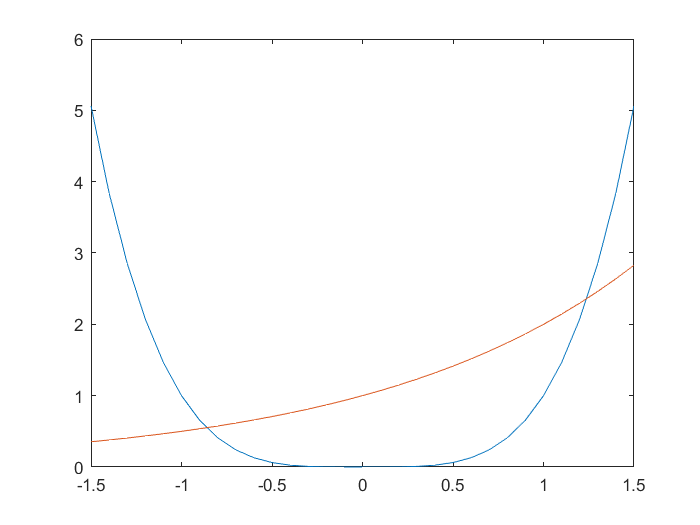

x = -1.5:0.1:1.5; plot(x, x.^4, x, 2.^x)

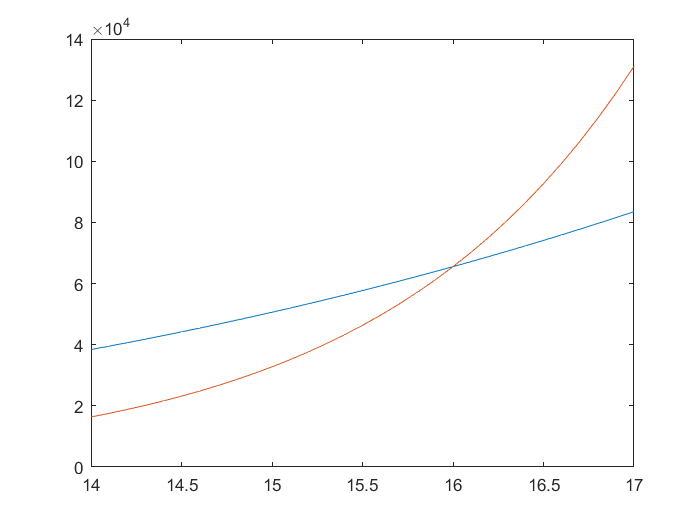

x = 14:0.1:17; plot(x, x.^4, x, 2.^x)

r1 = fzero(@(x) x.^4-2.^x, -1)

r1 = -0.8613

r2 = fzero(@(x) x.^4-2.^x, 1)

r2 = 1.2396

r3 = fzero(@(x) x.^4-2.^x, 16)

r3 = 16

syms x; double(subs(x.^4-2.^x, x, r1))

ans = -1.5091e-16

double(subs(x.^4-2.^x, x, r2))

ans = 5.5107e-16

double(subs(x.^4-2.^x, x, r3))

ans = 0

syms x real; symroots = solve(2^x-x^4==0) % lambertw function

$$symroots = \left(\begin{array}{c} -\frac{4\,W_{0}\left(-\frac{\log\left(2\right)}{4}\right)}{\log\left(2\right)}\\ -\frac{4\,W_{0}\left(\frac{\log\left(2\right)}{4}\right)}{\log\left(2\right)}\\ -\frac{4\,W_{-1}\left(-\frac{\log\left(2\right)}{4}\right)}{\log\left(2\right)} \end{array}\right)$$